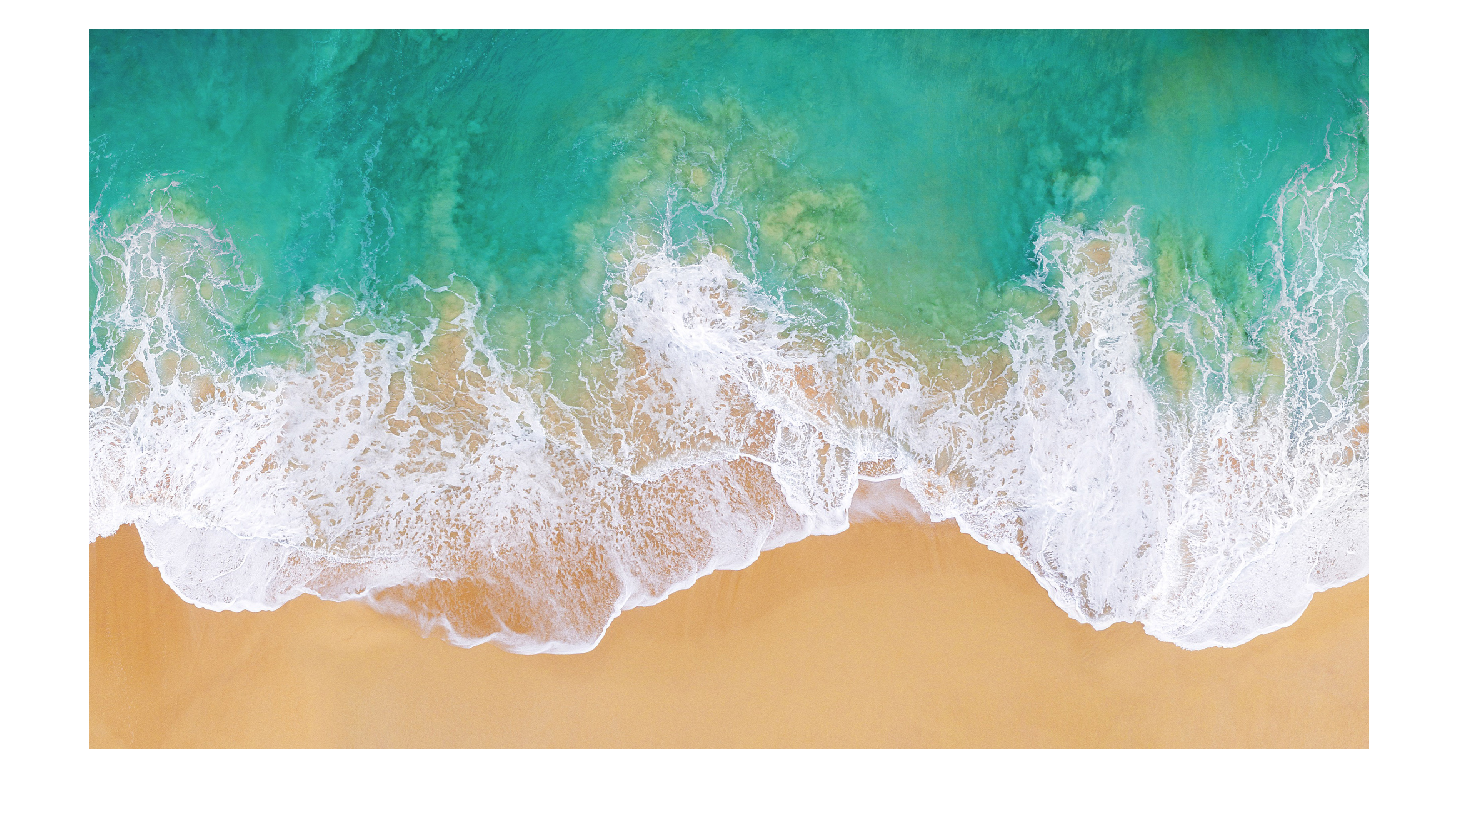

image = imread("wallhaven-83jleo.jpg");
imshow(image)

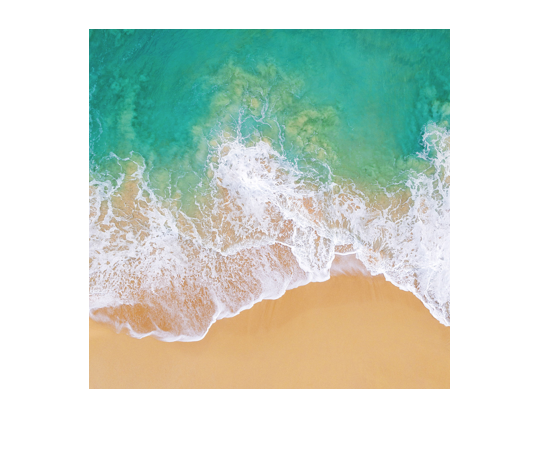

[p3, p4] = size(image);

imageResWidth = size(image,2);
imageResHeight = size(image,1);
aspectRatio = imageResWidth / imageResHeight;

targetSizeSquarePx = 360;

precroppedSizeWidthPx = ceil(aspectRatio * targetSizeSquarePx);
precroppedSizeHeightPx = targetSizeSquarePx;

image = imresize(image, [precroppedSizeHeightPx precroppedSizeWidthPx]);
% figure ,imshow(image);

i3_start = floor((precroppedSizeHeightPx - targetSizeSquarePx) / 2); % or round instead of floor; using neither gives warning
if i3_start == 0
    i3_start = i3_start + 1;
end
i3_stop = min(precroppedSizeHeightPx, i3_start + targetSizeSquarePx);

i4_start = floor((precroppedSizeWidthPx - targetSizeSquarePx) / 2);
if i4_start == 0
    i4_start = i4_start + 1;
end
i4_stop = min(precroppedSizeWidthPx, i4_start + targetSizeSquarePx);

image = image(i3_start:i3_stop, i4_start:i4_stop, :);
figure ,imshow(image);